# Counting Money with Connected Components

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

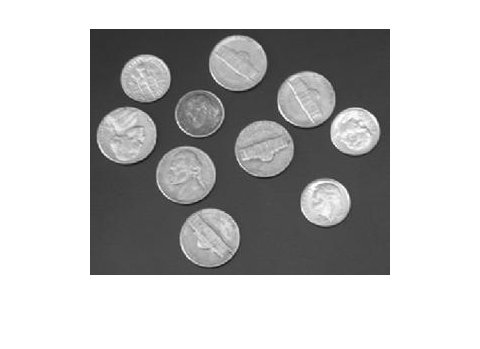

coins = imread("./images/coins.jpg");
imshow(coins)

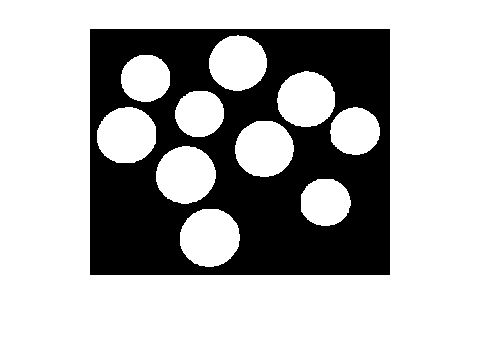


coinsMask = imbinarize(coins);
coinsMask = imfill(coinsMask, "holes");
imshow(coinsMask)

## Task 1

You can filter connected components by size using `bwpropfilt`.

`compFilt` `=` `bwpropfilt``(``BW``,``"Area"``,``range``)``;`

The range of sizes you want to keep is passed as a two-element vector.

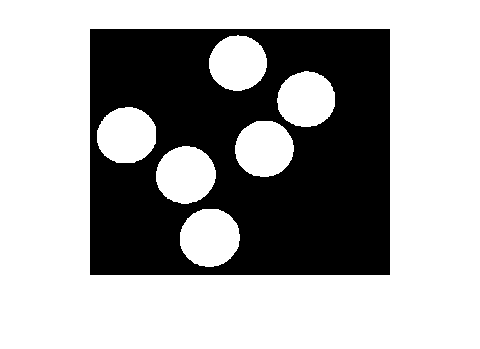

nickel = bwpropfilt(coinsMask, "Area", [2000 3000]);
imshow(nickel)

## Task 2

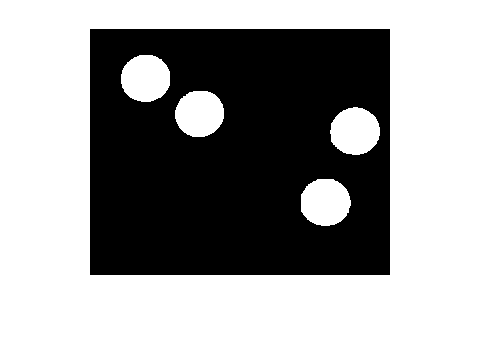

andDime = bwpropfilt(coinsMask, "Area", [0 2000]);
imshow(andDime)

## Task 3

You can find the connected components of a binary image with `bwconncomp`.

`CC` `=` `bwconncomp``(``BW``)`

The output is a struct containing information about the connected components.

nickelCC = bwconncomp(nickel)

nickelCC = struct with fields:
    Connectivity: 8
       ImageSize: [246 300]
      NumObjects: 6
    PixelIdxList: {[2643×1 double]  [2691×1 double]  [2757×1 double]  [2522×1 double]  [2608×1 double]  [2545×1 double]}


## Task 4

The struct identifying connected components contains information about them like the number of objects and the pixels that make up each component.

You can extract a field using dot notation.

`CC.PixelIdList`

numNickels = nickelCC.NumObjects

numNickels = 6

## Task 5

andDimeCC = bwconncomp(andDime)

andDimeCC = struct with fields:
    Connectivity: 8
       ImageSize: [246 300]
      NumObjects: 4
    PixelIdxList: {[1851×1 double]  [1804×1 double]  [1883×1 double]  [1865×1 double]}


numDimes = andDimeCC.NumObjects

numDimes = 4

## Task 6

Now that you have the number of nickels and dimes, you can use this to calculate the amount of money. Nickels are worth $0.05, and dimes are worth $0.10.

total = numNickels*.05 + numDimes*.1

total = 0.7000